# **Multiple point-Bayesian inference**

## **1 - INITIALIZE UQLAB**

clc;clear all;close all;
clearvars
rng(100,'twister')
uqlab

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
C:\NY2023\D_document\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



global S V number st mv myPCE

## 2 - Experiment of design (Uniform LHS)

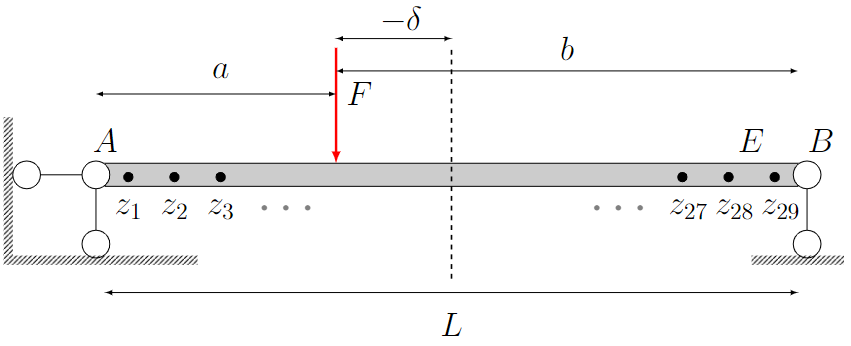

        b_b = 0.15; % beam width  (m)

        b_h = 0.3; % beam height (m)

        L = 30; % beam length (m)

**Computational model:**

$a = \frac{L}{2}- \delta$;$b = \frac{L}{2}+ \delta$


$$\mathcal{M}(\vec{\theta}) = \frac{F b  z  [(L^2 - b^2) - z^2]}{6LEI} \ \ \   \ \ \ \ \ \ \ z \le a$$
 


$$\mathcal{M}(\vec{\theta})  =  \frac{F b  [\frac{L}{b} (z - a)^3 + (L^2 - b^2)z-z^3]}{6LEI} \ \ \ \ z> a
$$



$$\vec{\theta} = [E,\delta,F,z];\vec{z} = [z_1,z_2,...,z_{28},z_{29}];$$


 $E $ is elastic modulus; $\delta$ is the loading postion, *F *is the loading force

$\vec{z} $is the different measurement points along the beam;

$\mathcal{M}$ is the FE model; $Y_i$ is the measurement data; $N$ is the number of experiment expNum.

Create a MODEL from the function file:

% %LHS sampling number

p = 1;
N = 100;
%Number of PCs

N_PCs = 20; 

%E experiment design

E_lhs = lhsdesign(N, p, 'criterion', 'none');
lower_limit_E = 10e9;
upper_limit_E = 50e9;
E_Uniform_sample = lower_limit_E + E_lhs * (upper_limit_E - lower_limit_E);
size(E_Uniform_sample)

ans =    100     1


%delta experiment design

delta_lhs = lhsdesign(N, p, 'criterion', 'none');
lower_limit_delta = -10;
upper_limit_delta = 10;
delta_Uniform_sample = lower_limit_delta + delta_lhs * (upper_limit_delta - lower_limit_delta);
size(delta_Uniform_sample)

ans =    100     1


% %  F experiment design
% 
F_lhs = lhsdesign(N, p, 'criterion', 'none');
lower_limit_F = 20000;
upper_limit_F = 60000;
F_Uniform_sample = lower_limit_F + F_lhs * (upper_limit_F - lower_limit_F);
size(F_Uniform_sample)

ans =    100     1


%Catenate E, delta
LHS_sample_total = [E_Uniform_sample delta_Uniform_sample F_Uniform_sample];	%

LHS_sample = LHS_sample_total(1:round(0.9*N),:);
LHS_validate = LHS_sample_total(round(0.9*N)+1:end,:);
size(LHS_sample)

ans =     90     3


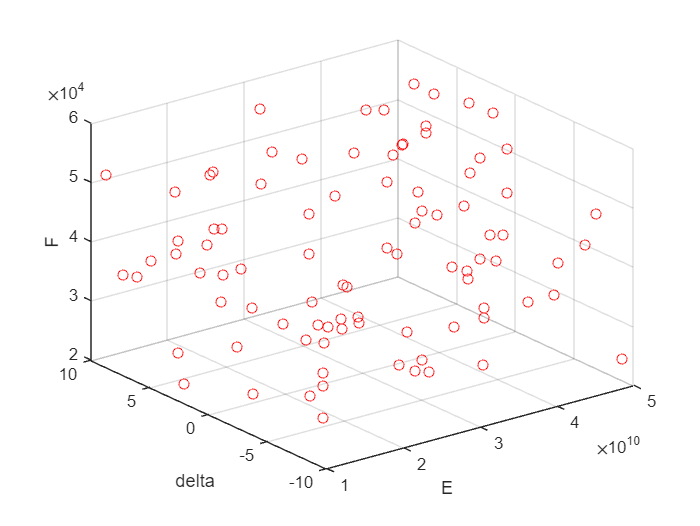

%plot LHS sampling
scatter3(LHS_sample(:,1),LHS_sample(:,2),LHS_sample(:,3),'r')
xlabel('E');ylabel('delta');zlabel("F");

Run FE simulation

FE_deflection = Deflection(LHS_sample);
size(FE_deflection)

ans =     90    29


FE_realization = [LHS_sample,FE_deflection];
size(FE_realization)

ans =     90    32


## 3 PCA reduce output dimensionality

Get the FE output

Y_Output = FE_realization(:,4:end);
size(Y_Output)

ans =     90    29


PCA reduction

[V,S,E,cumE,number]=princa(Y_Output,0.99);
number = N_PCs

number = 20

% save S S;
% save V V;
% save number number;


Plot the cumulative contribution vs number of PCA component

N_PCA = size(cumE,1)

N_PCA = 29

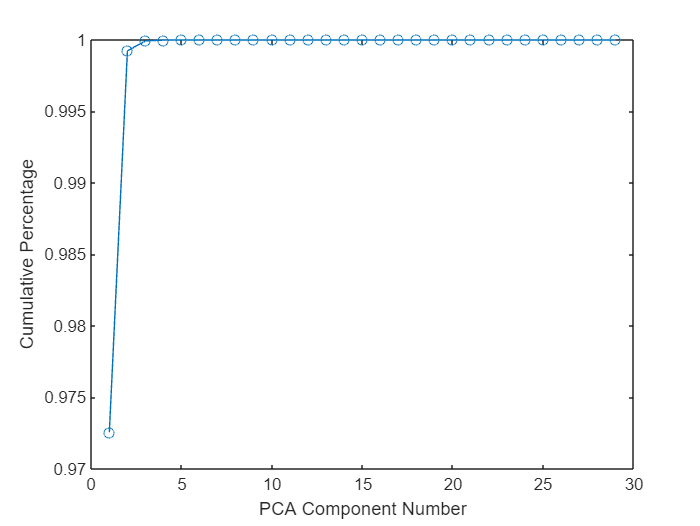

plot(1:N_PCA,cumE,'-o')
xlabel('PCA Component Number');
ylabel("Cumulative Percentage");

## 4 PCA truncation error

Reconstruct the output

close all;
[m, n] = size(S);  % Gets the dimensions of S
mv = mean(Y_Output);  % The mean of the raw data
st = std(Y_Output);   % Standard deviation of the original data
% save st st;
% save mv mv;
Y_ouput_reconstructed = S(:, 1:number) * V(:, 1:number)';
% De-normalize the score for each principal component
for i = 1:size(Y_ouput_reconstructed, 2)
    Y_ouput_reconstructed(:, i) = Y_ouput_reconstructed(:, i) * st(i) + mv(i);
end

size(Y_ouput_reconstructed)

ans =     90    29


modelling error of PCA truncation

PCA_loss =abs(Y_Output - Y_ouput_reconstructed);
size(PCA_loss)

ans =     90    29


Cov_PCA_loss = cov(PCA_loss);
size(Cov_PCA_loss)

ans =     29    29


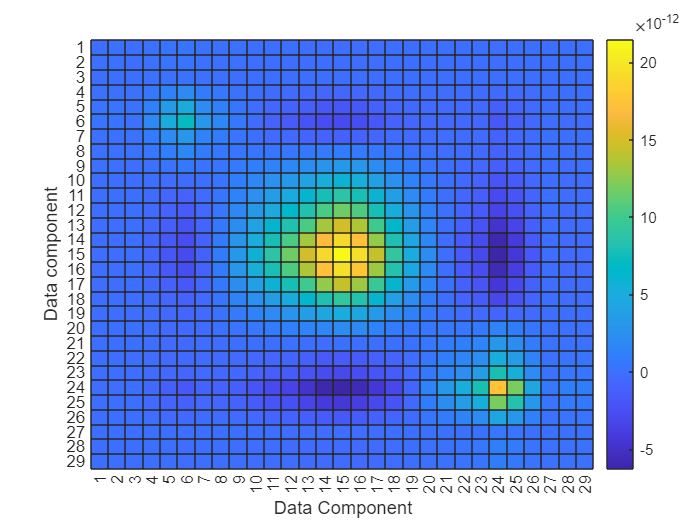

h = heatmap(Cov_PCA_loss);
h.FontSize = 10;
xlabel('Data Component');
ylabel('Data component');
h.Colormap = parula;

## 5 - PROBABILISTIC INPUT MODEL for PCE

Priors for E

InputOpts.Marginals(1).Type = 'Uniform';
minE = min(FE_realization(:,1));
maxE = max(FE_realization(:,1));
InputOpts.Marginals(1).Parameters  = [minE maxE];

Priors for delta

InputOpts.Marginals(2).Type = 'Uniform';
mindelta = min(FE_realization(:,2));
maxdelta = max(FE_realization(:,2));
InputOpts.Marginals(2).Parameters  = [mindelta maxdelta];

Priors for F

InputOpts.Marginals(3).Type = 'Uniform';
minF = min(FE_realization(:,3));
maxF = max(FE_realization(:,3));
InputOpts.Marginals(3).Parameters  = [minF maxF];

Create PCE input

myInput = uq_createInput(InputOpts);

## 6 - POLYNOMIAL CHAOS EXPANSION (PCE) METAMODELS $\tilde{\mathcal{M}}(r)$

Calculate the polynomial chaos expansion (PCE) coefficients.

Select PCE as the metamodeling tool in UQLab:

metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';

Select the sparse-favouring least-square minimization LARS for the 

PCE coefficients calculation strategy:

metaopts.Method = 'LARS';

Select the PCE options and create the PCE model:

metaopts.Degree = 2:15;

Experimental design

X = FE_realization(:,1:3);
Y = S(:, 1:number);
metaopts.ExpDesign.X = X;
metaopts.ExpDesign.Y = Y;
%metaopts.ExpDesign.Y = FE_realization(:,4:end);

Calculation

myPCE = uq_createModel(metaopts);

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 6 and qNorm 1.00 for output variable 1
Final LOO error estimate: 2.606188e-03
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 5 and qNorm 1.00 for output variable 2
Final LOO error estimate: 1.558111e-03
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 6 and qNorm 1.00 for output variable 3
Final LOO error estimate: 5.528926e-03
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 7 and qNorm 1.00 for output variab

Export the PCE strucuture

% save myPCE myPCE

## Sobol's indices

Select the metamodeling tool in UQLab and the polynomial chaos expansion (PCE) type:

SobolOpts.Type = 'Sensitivity';
SobolOpts.Method = 'Sobol';

Specify the maximum order of the Sobol' indices to be calculated:

SobolOpts.Sobol.Order = 1;

Run the sensitivity analysis:

mySobolAnalysisPCE = uq_createAnalysis(SobolOpts);


Starting Sobol' indices analysis...

Calculating PCE-based Sobol' indices up to order 1


uq_print(mySobolAnalysisPCE)

--------------------------------------------------
     Total Sobol' indices for output component 1
--------------------------------------------------
X1          X2          X3          
0.700129    0.099909    0.279118    
--------------------------------------------------
--------------------------------------------------
    First Order Sobol' indices for output component 1
--------------------------------------------------
X1          X2          X3          
0.629035    0.074649    0.218742    
--------------------------------------------------
Total cost (model evaluations): 0



## 7 - Yval vs YPCE (Principle component)

Get the validation set 

FE_deflection_total = Deflection(LHS_sample_total);
size(FE_deflection_total)

ans =    100    29


FE_realization_total = [LHS_sample_total,FE_deflection_total];
size(FE_realization_total)

ans =    100    32


PCA processing the validation set

Xval = FE_realization_total(:,1:3);
size(Xval)

ans =    100     3


Yval_original = FE_realization_total(:,4:end);
size(Yval_original)

ans =    100    29


[V_val,S_val,E_val,cumE_val,number_val]=princa(Yval_original,0.99);

Plot the cumulative contribution vs number of PCA component of validation set

number_val = N_PCs

number_val = 20

N_PCA = size(cumE,1)

N_PCA = 29

plot(1:N_PCA,cumE,'-o')
xlabel('Yval PCA Component Number');
ylabel("Cumulative Percentage");

Evaluate the full model response at the validation sample points:

Yval = S_val(:, 1:number_val);

size(Yval)

ans =    100    20


Responses for PCE 

YPCE= uq_evalModel(myPCE,Xval);

Yval vs YPCE

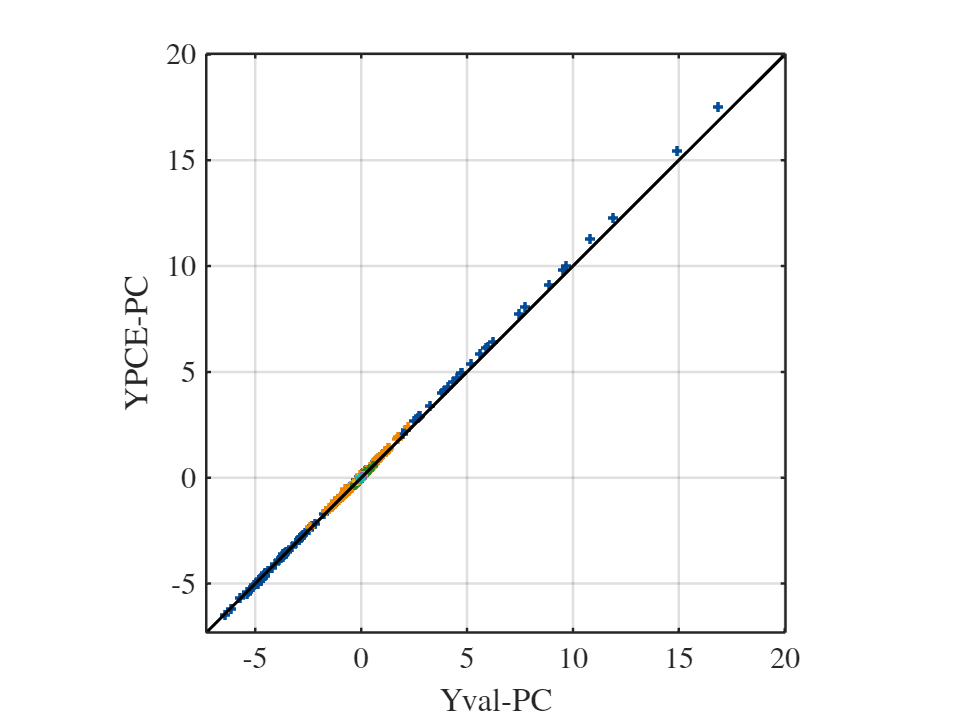

close all;
uq_figure
uq_plot(Yval, YPCE, '+')
hold on
uq_plot([min(Yval,[],'all') max(Yval,[],'all')], [min(Yval,[],'all') max(Yval,[],'all')], 'k')
hold off
axis equal
axis([min(Yval,[],'all') max(Yval,[],'all') min(Yval,[],'all') max(Yval,[],'all')])
xlabel('Yval-PC');
ylabel('YPCE-PC');
box on;

## 10 - Define the priors for F and discrepancy $\sigma$

## **Note: priors for F are different from input models above**

By default, UQlab assumes an independent and identically distributed discrepancy

$\varepsilon \sim \mathcal{N}(0,\mu_{y}^2)$, with $\mu_{y} = \frac{1}{N}\sum_{i = 1}^{N}y_i$

#### synthetic ground truth with 3% noise 

E = 37e9;delta = -3.15; F = 28000N; noise =0

Measurement1 = GroundTruth(3.7e+10,-3,2.8e+04,1,0.0);
N_Size_Measurement1 = size(Measurement1,2)

N_Size_Measurement1 = 29

Measurement2 = Beam_elongation([3.7e+10]);
size(Measurement2)

ans =      1     1



Measurement_All = [Measurement1 Measurement2];
size(Measurement_All)

ans =      1    30


 priors

%Priors on E
PriorOpts.Marginals(1).Name = 'E';               % E
PriorOpts.Marginals(1).Type = 'Gaussian';
PriorOpts.Marginals(1).Moments = [30e9 5e9];   % (N)
PriorOpts.Marginals(1).Bounds = [20e9 50e9];

%Priors on delta
PriorOpts.Marginals(2).Name = 'delta';               % Delta
PriorOpts.Marginals(2).Type = 'Gaussian';
PriorOpts.Marginals(2).Moments = [3 5];   % (N)
PriorOpts.Marginals(2).Bounds = [-9 9];

%Priors on F
PriorOpts.Marginals(3).Name = 'F';               % Loading F
PriorOpts.Marginals(3).Type = 'Gaussian';
PriorOpts.Marginals(3).Moments = [35000 5000];   % (N)
PriorOpts.Marginals(3).Bounds = [15000 45000];

% %Priors on P
% PriorOpts.Marginals(4).Name = 'P';               % Loading F
% PriorOpts.Marginals(4).Type = 'Gaussian';
% PriorOpts.Marginals(4).Moments = [40000 50];   % (N)
% PriorOpts.Marginals(4).Bounds = [39e3 41e3];


PriorOpts.Marginals(4).Name = 'Sigma2_1';               % sigma2_1
PriorOpts.Marginals(4).Type = 'Uniform';
sigma2 = mean(Measurement1(:,:),"all");
PriorOpts.Marginals(4).Parameters  = [0 sigma2.^2];


PriorOpts.Marginals(5).Name = 'Sigma2_2';               % sigma2_2
PriorOpts.Marginals(5).Type = 'Uniform';
sigma2 = mean(Measurement2(:,:),"all");
PriorOpts.Marginals(5).Parameters  = [0 sigma2.^2];



myPriorDist = uq_createInput(PriorOpts);


## 11 - Define the custom-loglikelihood  and measurement data for UQlab calculation


$$\ell\mathcal{L} ({\vec{\theta}},{\epsilon} \mid {Y}) = \prod_{i=1}^{N}\frac{1}{(2\pi)^{{3}/2}\det({\Sigma}(\epsilon))^{1/2}}\exp\left(-\frac{1}{2}\left({Y_i} - \mathcal{M}(\vec{\theta})\right)^{{T}} {\Sigma}(\epsilon)^{-1}\left({Y_i} - \mathcal{M}(\vec{\theta})\right)\right)$$



myData.y = Measurement_All;
size(myData.y)

ans =      1    30


myData.Name = 'Measurement on 29 points along the beam';

Loglikelihood still follows the Gaussian discrepancy criteria

myLogLikeli = @(params,y) LL1(params,y(:,1:29)) + 12*LL2(params,y(:,30));

## 12 - Solver options


Solver.Type = 'MCMC';
Solver.MCMC.Visualize.Parameters = [1 2 3 4 ];
Solver.MCMC.Visualize.Interval = 10;
Solver.MCMC.Sampler = 'AIES';
Solver.MCMC.Steps = 800;
Solver.MCMC.NChains = 30;
%Solver.MCMC.Proposal.PriorScale = 1e-3;

## 13 - Bayesian inference


Starting AIES...

|                              |   1.00%|#                             |   2.50%|#                             |   3.50%|##                            |   5.00%|##                            |   6.00%|##                            |   7.50%|###                           |   8.50%|###                           |  10.00%|###                           |  11.00%|####                          |  12.50%|####                          |  13.50%|#####                         |  15.00%|#####                         |  16.00%|#####                         |  17.50%|######                        |  18.50%|######                        |  20.00%|######                        |  21.00%|#######                       |  22.50%|#######                       |  23.50%|########                      |  25.00%|########                      |  26.00%|########                      |  27.50%|#########                     |  28.50%|#########                     |  30.00%|#########           

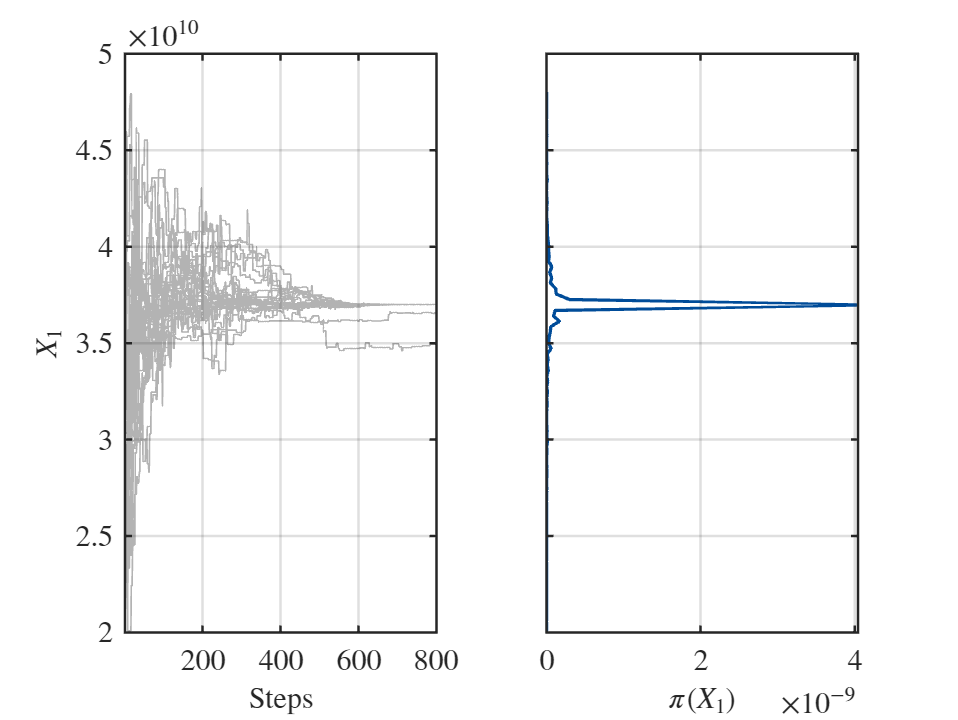

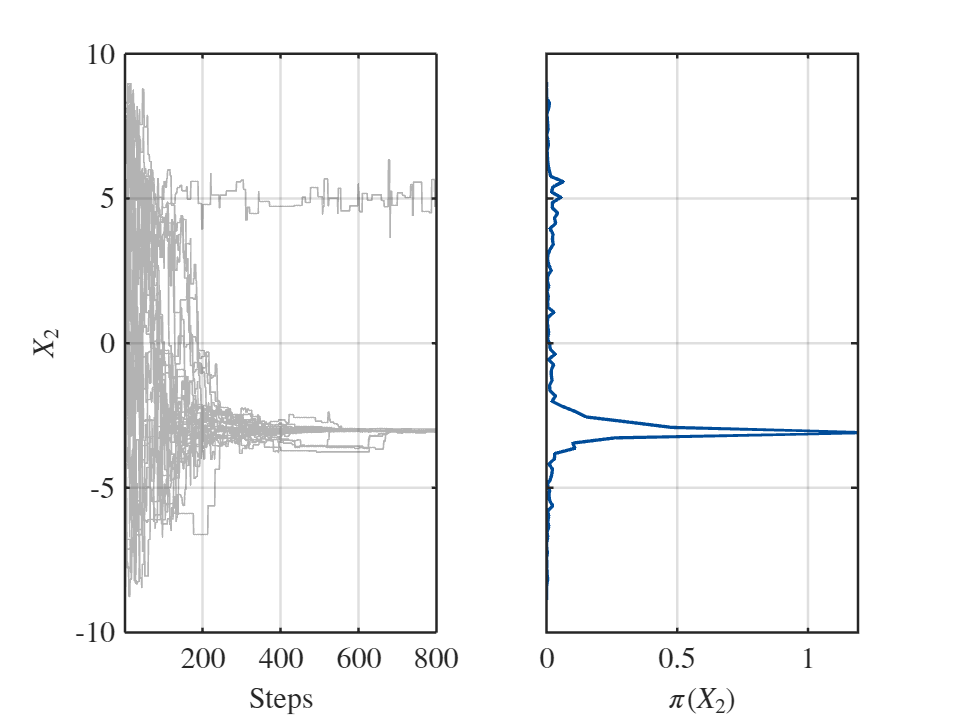

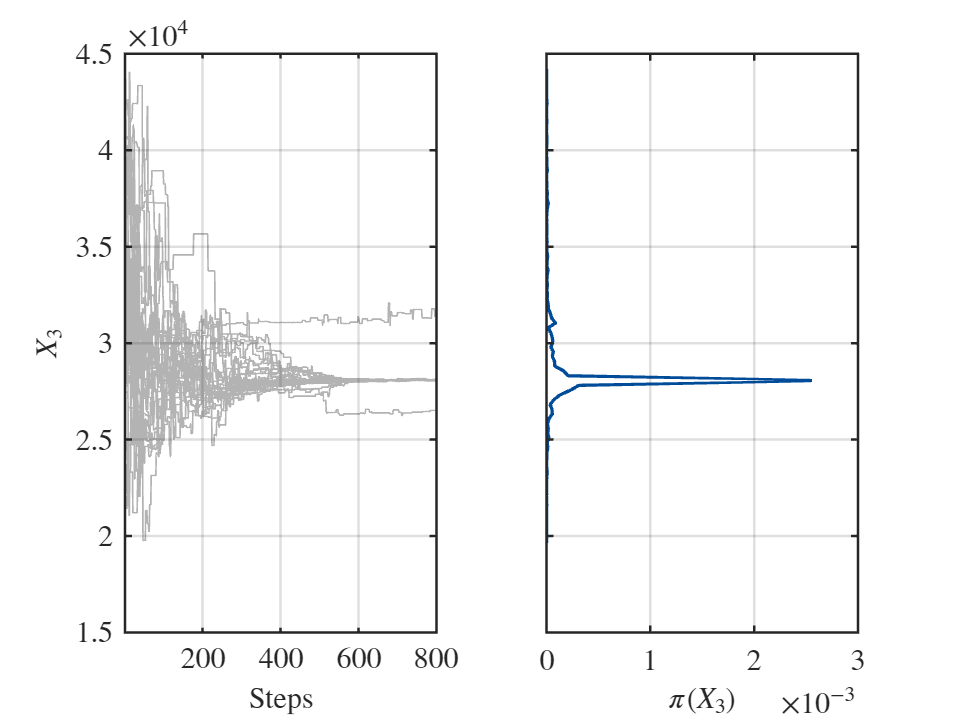

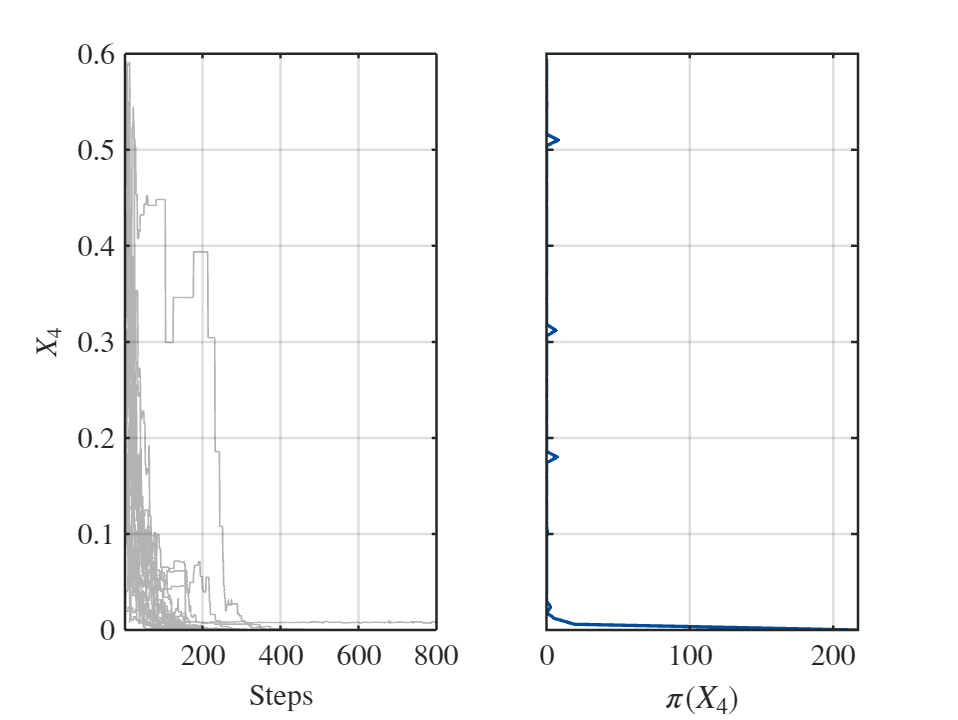


Finished AIES!


BayesOpts.LogLikelihood = myLogLikeli;
BayesOpts.Data = myData;
BayesOpts.Type = 'inversion';
BayesOpts.Solver = Solver;
BayesOpts.Prior = myPriorDist;
BayesAnalysis = uq_createAnalysis(BayesOpts);

## 14 - Post-processing

Burn in 70%; 


badChainsIndex1 = squeeze(BayesAnalysis.Results.Sample(end,1,:) > 3.5e10)';
badChainsIndex2 = squeeze(BayesAnalysis.Results.Sample(end,2,:) > 5)';

badChainsIndex3 = squeeze(BayesAnalysis.Results.Sample(end,2,:) > 27000)';

badChainsIndex = any([badChainsIndex1; badChainsIndex2; badChainsIndex3]);
uq_postProcessInversionMCMC(BayesAnalysis,'pointEstimate','MAP','percentiles',[0.05,0.95],'burnin',0.7,'badChains',badChainsIndex);
%uq_postProcessInversionMCMC(BayesAnalysis,'pointEstimate','MAP','percentiles',[0.05,0.95],'burnin',0.7);

uq_print(BayesAnalysis);
%uq_postProcessInversion(BayesAnalysis,'priorPredictive',1000);
%uq_display(BayesAnalysis);

## 16 -  90% error band on predictive posterior

### 90% confidence interval for E and $\delta$,F

set 90%  = 95%- 5%

Obtained the lower bound and upper bound for E , $\delta$ ,F

E_5_LowB = BayesAnalysis.Results.PostProc.Percentiles.Values(1,1);
size(E_5_LowB)

E_95_UpperB = BayesAnalysis.Results.PostProc.Percentiles.Values(2,1);
size(E_95_UpperB)

delta_5_LowB = BayesAnalysis.Results.PostProc.Percentiles.Values(1,2);
size(delta_5_LowB)

Delta_95_UpperB = BayesAnalysis.Results.PostProc.Percentiles.Values(2,2);
size(Delta_95_UpperB)


F_5_LowB = BayesAnalysis.Results.PostProc.Percentiles.Values(1,3);
disp(F_5_LowB)

F_95_UpperB = BayesAnalysis.Results.PostProc.Percentiles.Values(2,3);
disp(F_95_UpperB)



N_predict = 50

% sampling on E
E_90_sample_O = linspace(E_5_LowB,E_95_UpperB,N_predict)';
size(E_90_sample_O)

%Shuffle the order 
shuffledIndices = randperm(length(E_90_sample_O));
E_90_sample = E_90_sample_O(shuffledIndices);
size(E_90_sample)


% sampling on delta
delta_90_sample_O = linspace(delta_5_LowB,Delta_95_UpperB,N_predict)';
size(delta_90_sample_O)

%Shuffle the order 
shuffledIndices = randperm(length(delta_90_sample_O));
delta_90_sample = delta_90_sample_O(shuffledIndices);
size(delta_90_sample)

% sampling on F
F_90_sample_O = linspace(F_5_LowB,F_95_UpperB,N_predict)';
size(F_90_sample_O)

%Shuffle the order 
shuffledIndices = randperm(length(F_90_sample_O));
F_90_sample = F_90_sample_O(shuffledIndices);
size(F_90_sample)



%plot the sampling
figure
scatter3(E_90_sample,delta_90_sample,F_90_sample,'*');
xlabel('E');
ylabel('\delta');
zlabel('F');

Predictive FE realization

Predict_sample = [E_90_sample,delta_90_sample,F_90_sample];
size(Predict_sample)

%Loop to get the predictive FE deflection

YPCE_Predict = [];

for i = 1:N_predict
    
    Xval_Predict = Predict_sample(i,:);   

    PCA_PCE = uq_evalModel(myPCE,Xval_Predict);
    Deflection = PCA_PCE* V(:, 1:number)' ;

        for j = 1:size(Deflection, 2)
            Deflection(:, j) = Deflection(:, j) * st(j) + mv(j);
        end

    YPCE_Predict = [YPCE_Predict;Deflection];
    


end

size(YPCE_Predict)

Spline curve fitting to smooth the line for the 90CI

x = 1:29;%29 measurement position along the beam

for i = 1:size(YPCE_Predict,1)
    
    P = polyfit(x,YPCE_Predict(i,:),3);
    xi = 1:1:29;
    YPCE_Predict_Poly(i,:) = polyval(P,xi);
end
size(YPCE_Predict_Poly)

Loop to fill the error band 90%CI

%loop to fill the error band
close all;

for i = 1:size(YPCE_Predict_Poly,1)-1
    hold on;
    fill([xi fliplr(xi)], [-YPCE_Predict_Poly(i,:) fliplr(-YPCE_Predict_Poly(i+1,:))], 'cyan', 'FaceAlpha', 1,'EdgeColor','none');
end

 hold on;
 
 xlabel('Beam length \it{L} \rm(m)','FontSize',10);
 pbaspect([1 0.3 1]);
 ax = gca;
 ax.XAxisLocation = 'top';
 ylabel('Deflection (m)','FontSize',10);
 box on;
 set(ax,'FontSize',10);
 yticks('auto');
 %ylim([-3.5 0])

scatter the measurement

x = 1:1:29;
size(x)

for i = 1: size(myData.y,1)
    scatter(x,-myData.y(i,:),'black','x');
    hold on;
end

draw the mean value of 90%CI

plot(xi,-mean(YPCE_Predict_Poly),'red','LineWidth',1.5);

legend

% rectangle('Position', [22, -2,0.5, 0.25], 'FaceColor', 'cyan');
% text(23, -1.85, '90% CI', 'FontSize', 8);
% text(22.15, -2.2, 'x  measurement points', 'FontSize', 8);
% 
% line([22,22.6],[-2.5,-2.5],'linestyle','-','color','red','LineWidth',1.0);
% text(23, -2.5, 'mean', 'FontSize', 8);

Plot the predictive individual lines

hold off;

% beam position

x_beam = 1:1:29

for i = 1:size(YPCE_Predict,1)
    
    plot(x_beam,-YPCE_Predict(i,:));
    hold on;
end
 xlabel('Beam length \it{L} \rm(m)','FontSize',10);
 pbaspect([1 0.3 1]);
 ax = gca;
 ax.XAxisLocation = 'top';
 ylabel('Predictive deflection (m)','FontSize',10);
 box on;
 set(ax,'FontSize',10);
 yticks('auto');
  yticks('auto');
 %ylim([-3.5 0])